This segment sets a common path for the code to work in any computer

CurrFPath = matlab.desktop.editor.getActiveFilename;
CurrFPath = CurrFPath(1:end-20);
cd(CurrFPath)


%Name of label
labelName = 'gangster'

labelName = 'gangster'


%Labels to train with
labels = 'gangster_labels.mat'

labels = 'gangster_labels.mat'


%Name of the detector
detectorName = 'gangster_detector.mat'

detectorName = 'gangster_detector.mat'

## Detector Training

First we load the label to train with

load(labels)

This segment extracts the specific label we want and also filters images without labels

%Create training data from ground truth
    %In case of multiple labels in the object:
gangster_truth = selectLabels(gTruth,labelName)

gangster_truth =   groundTruth with properties:

          DataSource: [1×1 groundTruthDataSource]
    LabelDefinitions: [1×5 table]
           LabelData: [45×1 table]


%extracts a subset of ground truth dataset
training_data = objectDetectorTrainingData(gangster_truth)

training_data = 45×2 table
                                 imageFilename                                    gangster  
    ________________________________________________________________________    ____________

    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data/Gate10_A.jpg'}    {1×4 double}
    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data/Gate11_A.jpg'}    {1×4 double}
    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data/Gate11_B.jpg'}    {1×4 double}
    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data/Gate12_A.jpg'}    {1×4 double}
    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data/Gate12_B.jpg'}    {1×4 double}
    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data/Gate13_A.jpg'}    {1×4 double}
    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data/Gate13_B.jpg'}    {1×4 double}
    {'/home/v3nu5/Documents/VantTec/matlab_labeler/train_data/Gate1

summary(training_data)

Variables:

    imageFilename: 45×1 cell array of character vectors

    gangster: 45×1 cell



%train de ACF detector
detector = trainACFObjectDetector(training_data,'NumStages', 10)

ACF Object Detector Training
The training will take 10 stages. The model size is 67x47.
Sample positive examples(~100% Completed)
Compute approximation coefficients...Completed.
Compute aggregated channel features...Completed.
--------------------------------------------
Stage 1:
Sample negative examples(~100% Completed)
Compute aggregated channel features...Completed.
Train classifier with 45 positive examples and 225 negative examples...Completed.
The trained classifier has 19 weak learners.
--------------------------------------------
Stage 2:
Sample negative examples(~100% Completed)
Found 225 new negative examples for training.
Compute aggregated channel features...Completed.
Train classifier with 45 positive examples and 225 negative examples...Completed.
The trained classifier has 26 weak learners.
--------------------------------------------
Stage 3:
Sample negative examples(~100% Completed)
Found 138 new negative examples for training.
Compute aggregated channel features...Com

detector =   acfObjectDetector with properties:

             ModelName: 'gangster'
    ObjectTrainingSize: [67 47]
       NumWeakLearners: 56


save(detectorName,'detector');

Test del detector

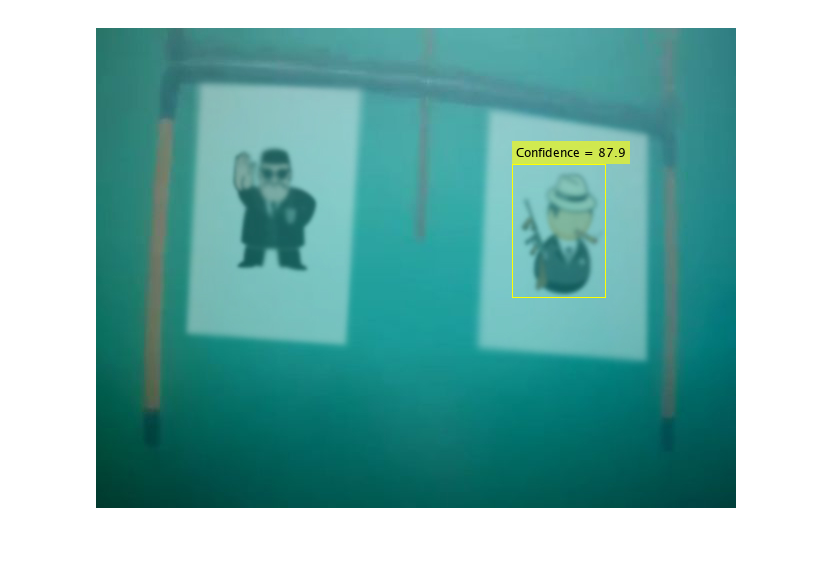

cd val_data/

img = imread('Gate25_B.jpg');

[bboxes,scores] = detect(detector,img);

%Display the detection results and insert the bounding boxes for objects into the image.

for i = 1:length(scores)
   annotation = sprintf('Confidence = %.1f',scores(i));
   img = insertObjectAnnotation(img,'rectangle',bboxes(i,:),annotation);
end

figure
imshow(img)


cd ../